clear all;
load impulse_responses.mat
warning('off');

% 
fs=16000;
num_samples=500000;
num_interferers=4;

[s1,~] = audioread('clean_speech.wav');
[babble, ~] = audioread('babble_noise.wav');
[clean_speech_2, ~] = audioread('clean_speech_2.wav');
[artificial_nonstat_noise, ~] = audioread('aritificial_nonstat_noise.wav');
[speech_noise, ~] = audioread('Speech_shaped_noise.wav');

s1 = s1(1:num_samples);
interference=[clean_speech_2(1:num_samples) babble(1:num_samples) artificial_nonstat_noise(1:num_samples) speech_noise(1:num_samples)].';

clean_speech_energy=sum(s1.^2);
for i =1:size(interference,1)
    interference(i,:)=norm_sig(interference(i,:),clean_speech_energy);
end
clean_speech = s1;

% num_samples=480000;
% s1=audioread('DataNormalized/s1_norm.wav');
% s2=audioread('DataNormalized/s2_norm.wav');
% s3=audioread('DataNormalized/s3_norm.wav');
% s4=audioread('DataNormalized/s4_norm.wav');
% s5=audioread('DataNormalized/s5_norm.wav');

% interference=[s2 s3 s4 s5].';


M=4; % Number of microphones
%read in impulse responses
H = struct2cell( load('impulse_responses.mat'));
%construct multiple sound_sources
x_time = zeros(4, num_samples);
s_time = zeros(4, num_samples); 
in_time=zeros(4, num_samples);

%speech2,babble, artificial, speech shaped noise
interference_ratio=[1,1,1,1];
SNR_mic_before = zeros(1, 4);
max_SNR=-10;
SNR_factor=0;
noise_inter=zeros([num_samples,1]);


for i = 1:M
    target_signal=conv(clean_speech,H{5}(i,:),"same");
    for j=1:num_interferers
        interferer=conv(interference(j,:),H{j}(i,:),"same")*interference_ratio(j);
        noise_inter=noise_inter+interferer.';
    end
    % 
    if i==1
        SNR_factor=sqrt(sum(target_signal.^2)/(10^(max_SNR/10)*sum(noise_inter.^2)));
    end
    % noise_inter=noise_inter*SNR_factor;
    signal=target_signal+noise_inter;
    x_time(i,:) = signal;
    x_time(1,:)=x_time(1,:)/max(x_time(1,:));
    s_time(i,:) = target_signal;
    in_time(i,:)=noise_inter;
    
    % Calculate the SNR
    SNR_mic_before(i) = 10 * log10(sum(abs(target_signal).^2) / sum(abs(signal - target_signal).^2));
    filename = sprintf('microphone%d.wav', i);
    audiowrite(filename, signal, fs);
end

SNR_mic_before

SNR_mic_before =    -7.4649  -13.4531  -14.8172  -16.8986


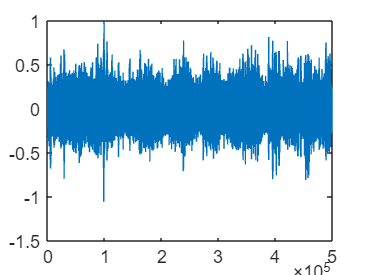


audiowrite("mic1.wav", x_time(1,:), fs);
plot(x_time(1,:))

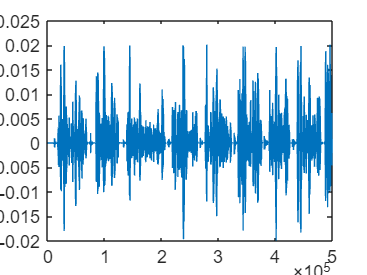

plot(s_time(1,:))



stoi(s1,x_time(1,:),16000)

ans = 0.4517

% Short time fourier transform
window_time=0.02;
K=window_time*fs;
Overlap=0.5;
[X, F, T] = stft(x_time.', fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength',320 );
L=size(X,2);
x_f_vad=stft(s_time(1,:).', fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength',320 );


% % Perform VAD
% threshold=0.005;
% vadResult = vad(x_f_vad, threshold);
% % Time axis for the original signal
% time = (0:length(x_time)-1) / fs;
% 
% % Time axis for the VAD result
% D = round(K * (1 - Overlap));  % Step size
% t_vad = (0:L-1) * D / fs;
% 
% 
% % Plotting
% figure;
% 
% % Plot the original signal
% 
% plot(time, x_time(1,:));
% xlabel('Time [s]');
% ylabel('Amplitude');
% legend('Audio Signal');
% hold on;
% % Plot the binary VAD result
% 
% plot(t_vad,(vadResult-0.5)*0.5, 'k', 'LineWidth', 1.5);
% xlabel('Time [s]');
% ylabel('VAD');
% title('Voice Activity Detection (VAD)');
% legend('VAD Result');
% hold off;


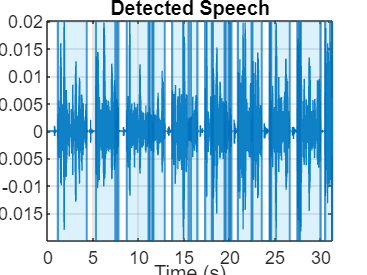

detectSpeech(s_time(1,:)',16000,"Window",hann(K,'periodic'),'OverlapLength',K/2)

l_speech=VAD_matlab(s_time(1,:)',K,0.5,16000);

speech_samples =        17760       68640
       84480      124320
      138720      205920
      218880      263040
      276480      293760
      300000      322560
      334080      376320
      389760      425280
      438720      479520
      487680      497760


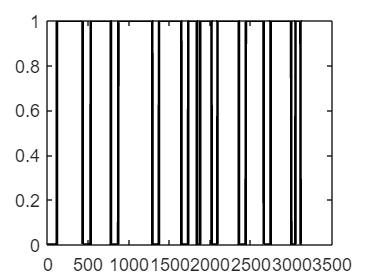

plot((l_speech), 'k', 'LineWidth', 1.5);

S_ds = zeros(K, L);
S_mvdr = zeros(K, L);
S_sdw=zeros(K, L);



R_x=zeros([4,4]);
R_n=zeros([4,4]);

alpha=0.9;
u=0.7;
epsilon=10^-17;


    for k = 1:K
        for l = 1:L
          curr_x=squeeze(X( k, l,:));
          if l==1
              R_n= curr_x*curr_x';
              R_x= curr_x*curr_x';
          else
                  if l_speech(l)==0
                      R_n = alpha.*R_x + (1-alpha).*curr_x*curr_x';                 
                  end
                R_x = alpha.*R_x + (1-alpha).*curr_x*curr_x';
          end
    
          %now to estimate the atf
            [U,V]=eig(R_x,R_n);
            % Extract eigenvalues
            eigenvalues = diag(V);
            [eig_sorted, sortedIndices] = sort(eigenvalues, 'descend');
            U_sorted = U(:, sortedIndices);
            a=U_sorted(:,1);
            sigma_s=(eig_sorted(1)-1);

            %calculate the RTF
            R_x_inv=pinv(R_x+epsilon*eye(4));
            w = (R_x_inv *a ) / (a'*R_x_inv * a);
            S_mvdr( k, l) = w' * curr_x;
    
            % SDW
            R_n_inv=pinv(R_n+epsilon*eye(4));
            w=sigma_s*R_n_inv*a/((a'*R_n_inv*a)*(sigma_s+u*pinv(a'*R_n_inv*a)));
            S_sdw( k, l) = w' * curr_x;
            
            %delay and sum beamformer
            w=a/(4);
            S_ds( k, l) = w' * curr_x;
        end
    end




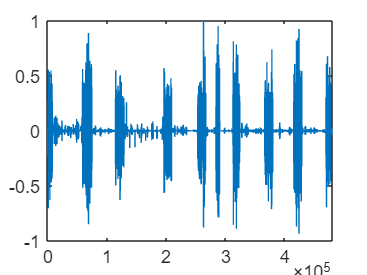

curr_test="test";
%delay sum
S_est=S_ds;
S_est(isnan(S_est))=0;
S_est(isinf(S_est))=0;
ss=real(istft(squeeze(S_est), fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength', 320));

ss=ss(10000:490000);
ss=ss/max(ss);
audiowrite('outputs/DS'+curr_test+".wav", ss, fs);

plot(ss)
ylim([-1,1])
xlim([0,480000])

SNR_out=10*log10(norm(ss,2)/norm(in_time(1,10000:490000).',2))

SNR_out = 11.8206

stoi(s1(10000:490000),ss,16000)

ans = 0.5518

stoi(s1(10000:490000),x_time(1,10000:490000),16000)

ans = 0.4513

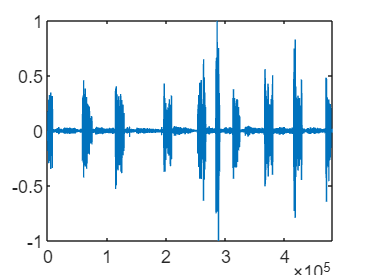

%MVDR
S_est=S_mvdr;
S_est(isnan(S_est))=0;
S_est(isinf(S_est))=0;
ss=real(istft(squeeze(S_est), fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength', 320));
audiowrite('outputs/mvdr'+curr_test+".wav", ss/max(ss(10000:end-10000)), fs);
ss=ss(10000:490000);
ss=ss/max(ss);
plot(ss)
ylim([-1,1])
xlim([0,480000])

SNR_out=10*log10(norm(ss,2)/norm(in_time(1,10000:490000).',2))

SNR_out = 9.9753

stoi(s1(10000:490000),ss,16000)

ans = 0.1713

stoi(s1(10000:490000),x_time(1,10000:490000),16000)

ans = 0.4513

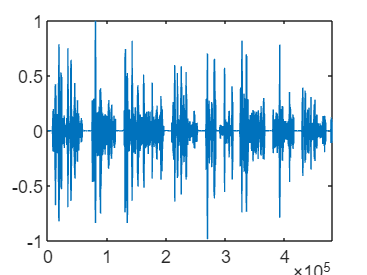

%SDW
S_est=S_sdw;
S_est(isnan(S_est))=0;
S_est(isinf(S_est))=0;
ss=real(istft(squeeze(S_est), fs, 'Window', hann(K, 'periodic'), 'OverlapLength', K/2, 'FFTLength', 320));
audiowrite('outputs/SDW'+curr_test+".wav", ss*500, fs);
ss=ss(10000:490000);
ss=ss/max(ss);
plot(ss)
ylim([-1,1]);
xlim([0,480000]);

SNR_out=10*log10(norm(ss,2)/norm(in_time(1,10000:490000).',2))

SNR_out = 11.5005

stoi(s1(10000:490000),ss,16000)

ans = 0.7066

stoi(s1(10000:490000),x_time(1,10000:490000),16000)

ans = 0.4513

audiowrite("signal_out.wav", ss,fs);

function signal_out = norm_sig(in_signal,target_energy)
    factor= sqrt(target_energy/sum(in_signal.^2));
    signal_out = in_signal *factor;
end
